**EPFL Spacecraft Team - CHESS Mission Design**

Arnaud Muller & Antoine Clout

Autumn 2020

clc
clear
close all

Read TUDAT propagation results

if (~exist('PropagationResults')) %#ok<*EXIST>
    PropagationResults= importdata('PropagationResults.dat');
end
Epochs=PropagationResults(:,1);
CartesianPos_C1= PropagationResults(:,2:4);
SRP_C1=PropagationResults(:,5);
CartesianPos_C2= PropagationResults(:,6:8);
SRP_C2= PropagationResults(:,9);

UTC_DateTime=epochToDate(Epochs);
Time=Epochs-Epochs(1);

X1=CartesianPos_C1(:,1);
Y1=CartesianPos_C1(:,2);
Z1=CartesianPos_C1(:,3);
X2=CartesianPos_C2(:,1);
Y2=CartesianPos_C2(:,2);
Z2=CartesianPos_C2(:,3);

3D Plots

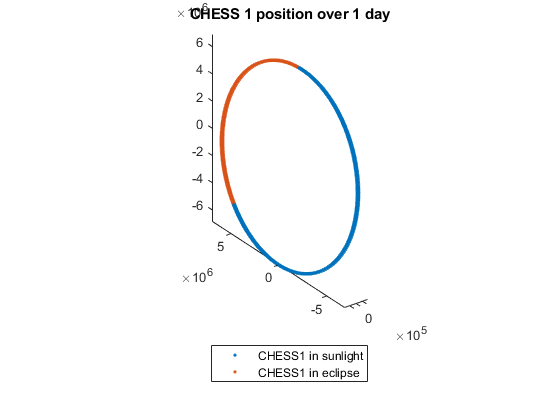

figure
plot3(X1(SRP_C1>0 & Time<86400),Y1(SRP_C1>0 & Time<86400),Z1(SRP_C1>0 & Time<86400),'.','DisplayName','CHESS1 in sunlight')
axis equal
hold on
plot3(X1(SRP_C1==0 & Time<86400),Y1(SRP_C1==0 & Time<86400),Z1(SRP_C1==0 & Time<86400),'.','DisplayName','CHESS1 in eclipse')
title('CHESS 1 position over 1 day')
legend('Location','Southoutside')

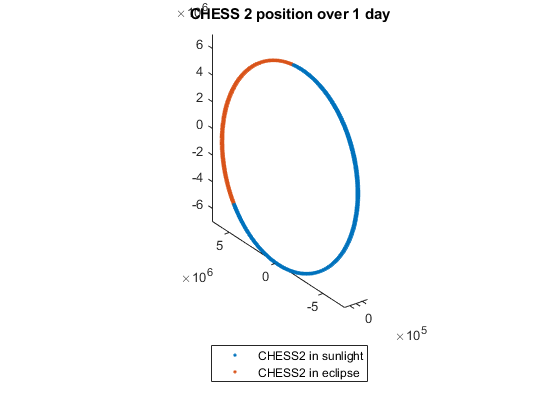



figure
plot3(X2(SRP_C2>0 & Time<86400),Y2(SRP_C2>0 & Time<86400),Z2(SRP_C2>0 & Time<86400),'.','DisplayName','CHESS2 in sunlight')
axis equal
hold on
plot3(X2(SRP_C2==0 & Time<86400),Y2(SRP_C2==0 & Time<86400),Z2(SRP_C2==0 & Time<86400),'.','DisplayName','CHESS2 in eclipse')
title('CHESS 2 position over 1 day')
legend('Location','Southoutside')

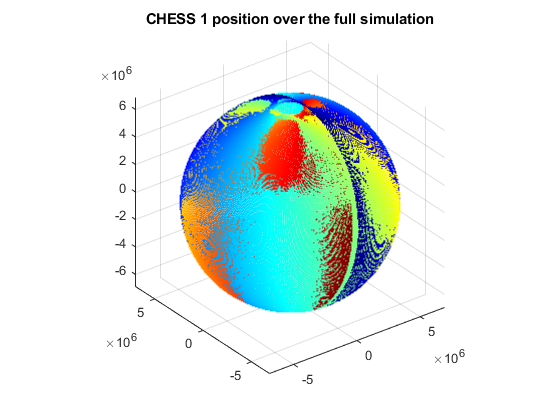


segColors = jet(length(X1)); % Choose a colormap
figure
scatter3(X1,Y1,Z1,1,segColors);
axis equal
title('CHESS 1 position over the full simulation')

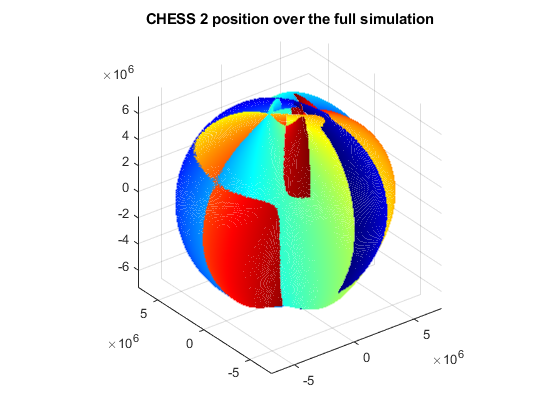


figure
scatter3(X2,Y2,Z2,1,segColors);
axis equal
title('CHESS 2 position over the full simulation')

Data Analysis

compteur = 0;
Eclipses_C1 = zeros(length(SRP_C1),1);
for k=1:length(SRP_C1)
    if SRP_C1(k) == 0
        Eclipses_C1(k) = compteur;
        compteur = 0;
    else
        compteur = compteur +1;    
    end
end
Eclipses_C1(k) = compteur;
Eclipses_Dates_C1=UTC_DateTime(Eclipses_C1>0);
clear compteur
Eclipses_C1=Eclipses_C1(Eclipses_C1 > 0);

compteur = 0;
Eclipses_C2 = zeros(length(SRP_C2),1);
for k=1:length(SRP_C2)
    if SRP_C2(k) == 0
        Eclipses_C2(k) = compteur;
        compteur = 0;
    else
        compteur = compteur +1;    
    end
end
Eclipses_C2(k) = compteur;
Eclipses_Dates_C2=UTC_DateTime(Eclipses_C2>0);
clear compteur
Eclipses_C2=Eclipses_C2(Eclipses_C2 > 0);

Data plots

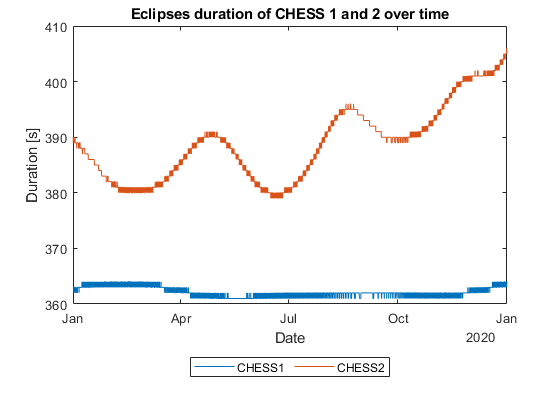

figure
plot(Eclipses_Dates_C1(2:end-1),Eclipses_C1(2:end-1),'DisplayName','CHESS1')
hold on
plot(Eclipses_Dates_C2(2:end-1),Eclipses_C2(2:end-1),'DisplayName','CHESS2')
title('Eclipses duration of CHESS 1 and 2 over time')
legend('Location','Southoutside','Orientation','horizontal')
xlabel('Date')
ylabel('Duration [s]')

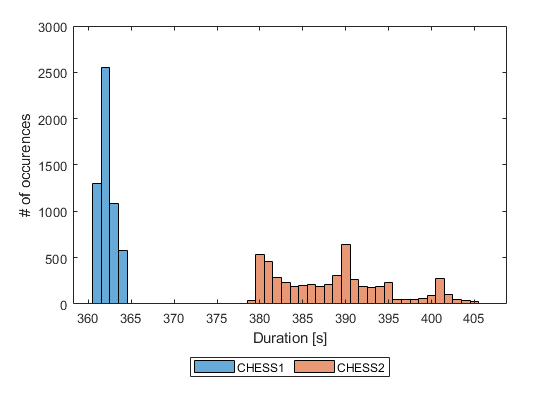


figure
title('Histogram of CHESS1 and 2 eclipses duration')
histogram(Eclipses_C1(2:end-1),'DisplayName','CHESS1')
hold on
histogram(Eclipses_C2(2:end-1),'DisplayName','CHESS2')
xlabel('Duration [s]')
ylabel('# of occurences')
legend('Location','Southoutside','Orientation','horizontal')


% figure
% boxplot([Eclipses_C1;Eclipses_C2],[repmat({'CHESS1'},length(Eclipses_C1),1);repmat({'CHESS2'},length(Eclipses_C2),1)])
% xlabel('Spacecraft')
% ylabel('Duration [s]')
% title('Eclipses durations stats over the full simulation')







**Compute chess1 eclipse duration as a function of the RAAN, find RAAN which maximizes eclipse duration (1200 local time SSO)**